# Show  Diagram FP demo

Use ShowDiagramFP function to show the Fuel-Product diagram.

### **Read Data Model**

file = "C:\Users\ctorr\Documents\Proyectos\TaesLab\Examples\cgam\cgam_model.json";
data = ReadDataModel(file);

### **Build Diagram FP**

Get the DiagramFP results info and save it into a file

res=DiagramFP(data,'SaveAs','DiagramFP.xlsx');

INFO: cMessageLogger. Diagram FP is saved in file DiagramFP.xlsx


### Plot Diagram FP

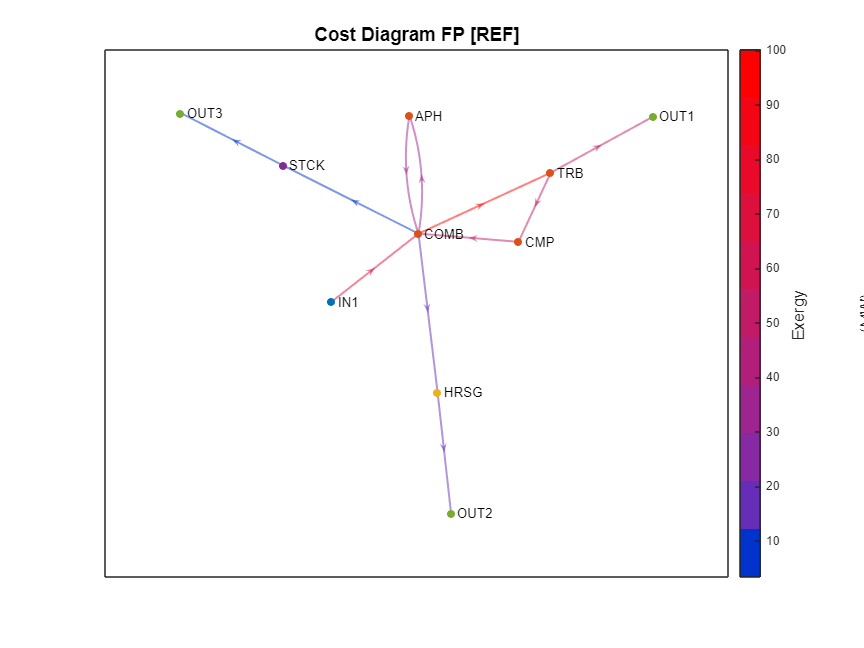

ShowGraph(res,'Graph',cType.Tables.COST_DIAGRAM_FP);

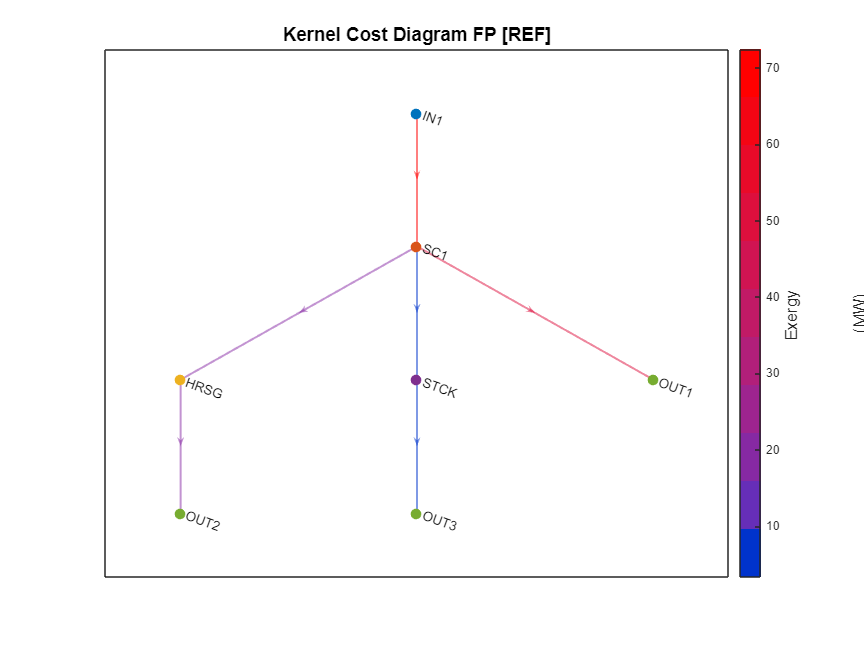

ShowGraph(res,'Graph',cType.Tables.KDIAGRAM_COST_FP);

printTable(getGroupsTable(res));


Graph Components

 Name   Components  
——————————————————————
 IN1    IN          
 COMB   SC1         
 CMP    SC1         
 TRB    SC1         
 APH    SC1         
 HRSG   HRSG        
 STCK   STCK        
 OUT1   OUT         
 OUT2   OUT         
 OUT3   OUT         



### Additional Help Information

help DiagramFP

 DiagramFP - Get the FP diagrams for a plant state.
    These diagrams can be represented graphically using the ShowGraph function, 
    or using external graphics software such as yEd, saving the adjacency tables
    of the graph in xlsx format.
   	
    Syntax
      res = DiagramFP(data,Name,Value);
 
    Input Arguments
      data - cReadModel Object containing the data model information.
 
    Name-Value Arguments
      State - Indicate one valid state to get exergy values. 
        char array
      Show -  Show results on console
        true | false (default)
      SaveAs - Name of the file where the results are saved.
        char array | string
 
    Output Arguments
      res - cResultInfo object contains the FP diagram tables
       The following tables are obtained:
        atfp - Diagram FP adjacency matrix                                     
        atcfp - Cost Diagram FP adjacency matrix
    
    Examples
      